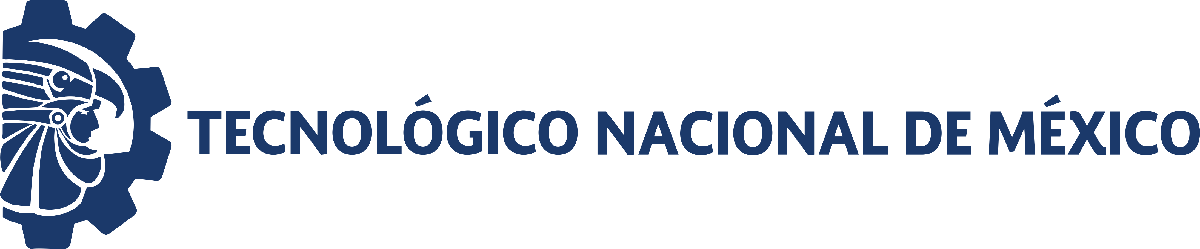                                 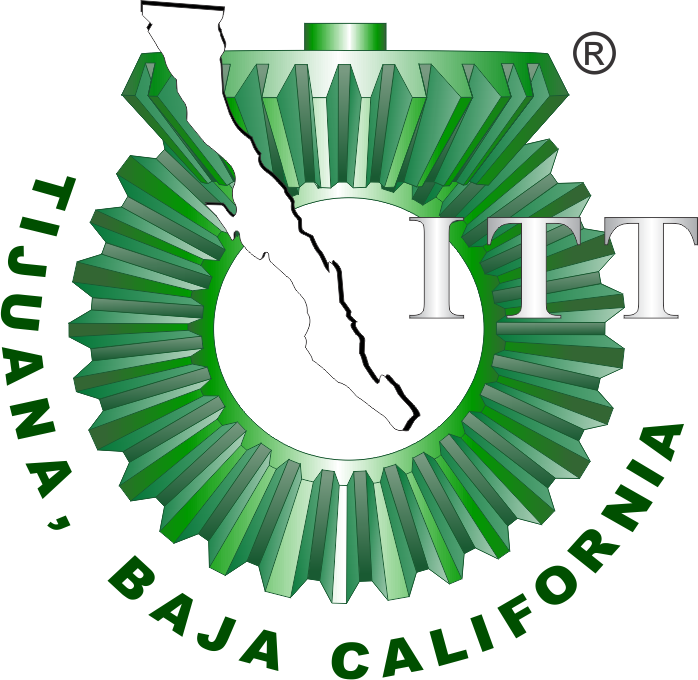

# Práctica tres: Sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

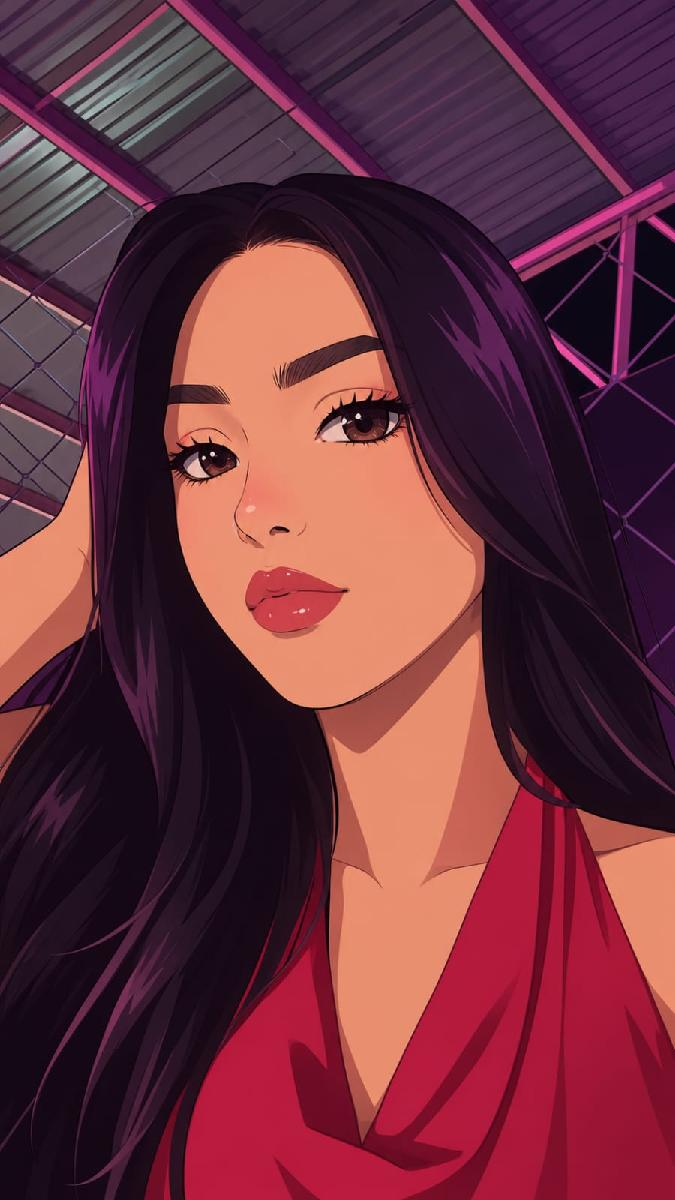

Nombre del alumno: **Castañeda Nieblas Lorena Lizel**

Número de control: **23210695**

Correo institucional: **l23210695@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Sist3')                

Unable to find system or file 'Sist3'.

parameters.StopTime = '15';           
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('P3D',parameters);     

## Modelo de EDOs

dt = 1e-3
t = (0:dt:10)';

F = zeros(length(t),1);
F(1/dt:2/dt)=1;

PID= interp1(X.t,X.PID,t,'previous');

par_control=[0.25,10e-6,100];
par_caso=[0.25,10e-6,100e-6,10e3];

Fs_control= musculoesqueletico(par_control,F,t);
Fs_caso=musculoesqueletico(par_caso,F,t);

plotsignals(t,F,Fs_control,Fs_caso,PID,'EDOsys')

plotsignals(x.t, x.F, x.Fs1, x.PID, x.Fsy, 'Respuestas')

function Fs=musculoesqueletico(par,F,t)

 alpha=par(1); Cs=par(2);cp=par(3);R=par(4);dt=t(2);
 n=round(t(end)/dt);
 x=zeros(length(t),1); x(1)=0;
 Fs=zeros(length(t),1); Fs(1)=0;
for i= 1:n
    x(i+1)=x(i)+((F(i)-x(i))/R*(Cp+Cs))*dt; %EDO
    Fs(i+1)=Cs*F(i)/(Cp+Cs)+(1-alpha-Cs/(Cp+Cs))*x(i);%Funcion
    end
end

## Respuesta a la simulación

function plotsignals(t,x1,x2,x3,x4,signal)

set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,10,5])
set(gca,'fontname','times new roman','fontsize',12)
hold on; grid off; box on;
    clr1 = [248, 178, 178]/255;
    clr2 = [175, 113, 157]/255;
    clr3 = [64, 61, 136]/255;
    clr4 = [0.5, 0.5, 0.5]/255;
    order = [clr1;clr2;clr3;clr4]; colororder(order)

  if signal == "Respuestas"
    plot(t,x1,'-','LineWidth',0.25,'Color',clr1)  %F(t)
    plot(t,x2,'--','LineWidth',0.25,'Color',clr2)  %Control
    plot(t,x3,'--','LineWidth',0.25,'Color',clr3)  %Caso
    plot(t,x4,':','LineWidth',1,'Color',clr4)     %PID Tratamiento
    L = legend('$F(t)$','$F_s(t):Control$','$F_s(t):Caso$','$PID(t):Tratamiento$');
end

set(L,'interpreter','latex','location','northoutside','orientation','horizontal','box','off')
xlabel('$t$ [s]','interpreter','latex')
ylabel('$F(t)$ [V]','interpreter','latex')
xlim([0 10]); xticks(0:1:10)
ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)
exportgraphics(gcf,[signal,'matlab.pdf'],'ContentType','vector')
end